# Differential Drive

Copyright 2018-2019 The MathWorks, Inc.

## Kinematic Model

This vehicle has two independently driven wheels which can be used to control forward and angular velocity.

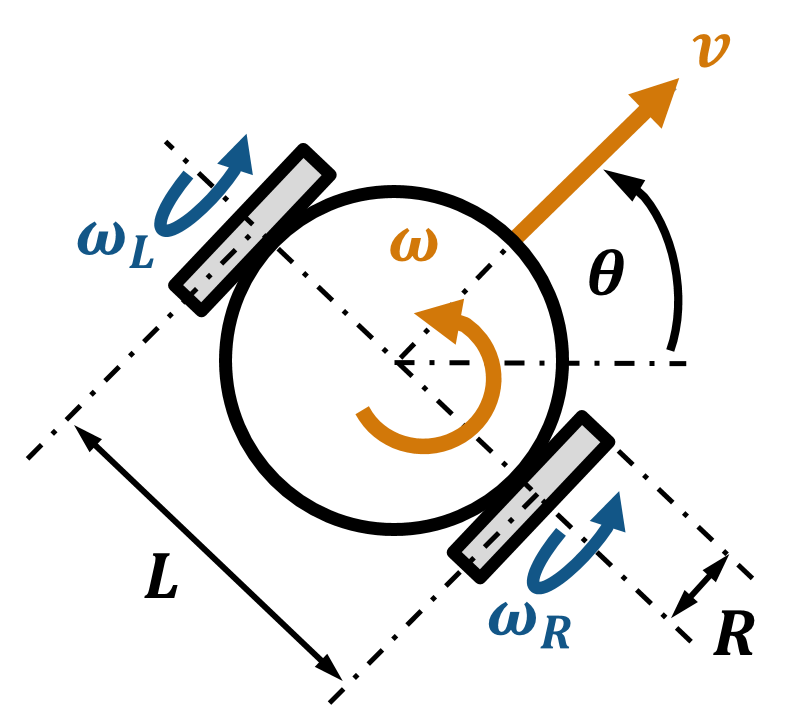

**Inputs:**

- Left and right wheel speeds $\omega_L$ and $\omega_R$, in rad/s

**Outputs**

- Linear velocity $v$, in m/s

- Angular velocity $\omega$, in rad/s

**Forward Kinematics**


$$v=\frac{R}{2}{\left(\omega_R +\omega_L \right)},  \text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\omega =\frac{R}{L}{\left(\omega_R -\omega_L \right)}$$


**Inverse Kinematics**


$$\omega_L =\frac{1}{R}{\left(v-\frac{\omega L}{2}\right)},  \text{   }\omega_R =\frac{1}{R}{\left(v+\frac{\omega L}{2}\right)}$$


## MATLAB Usage

Create a `DifferentialDrive` object

R = 0.1; % Wheel radius [m]
L = 0.5; % Wheelbase [m]
vehicle = DifferentialDrive(R,L)

vehicle =   DifferentialDrive with properties:

    wheelRadius: 0.1000
      wheelBase: 0.5000

Solve forward kinematics

wL = 1;
wR = -0.5;
[v,w] = forwardKinematics(vehicle,wL,wR)

v = 0.0250

w = -0.3000

Solve inverse kinematics

vRef = 0.2;
wRef = 0.5;
[wL,wR] = inverseKinematics(vehicle,vRef,wRef)

wL = 0.7500

wR = 3.2500

Reference examples:

- [Discrete-time kinematic simulation](matlab:edit mrsDiffDriveDiscrete)

- [Continuous-time kinematic simulation](matlab:edit mrsDiffDriveContinuous)

## Simulink Usage

Simulink blocks are in the **Kinematic Models > Differential Drive** section of the [block library](matlab:mobileRoboticsLib).

- Use the **Differential Drive Forward Kinematics** and **Differential Drive Inverse Kinematics** blocks to convert between body velocities and wheel velocities.

- Use the **Differential Drive Simulation** block to simulate the pose given wheel speeds as inputs. You can configure the initial pose and simulation sample time.

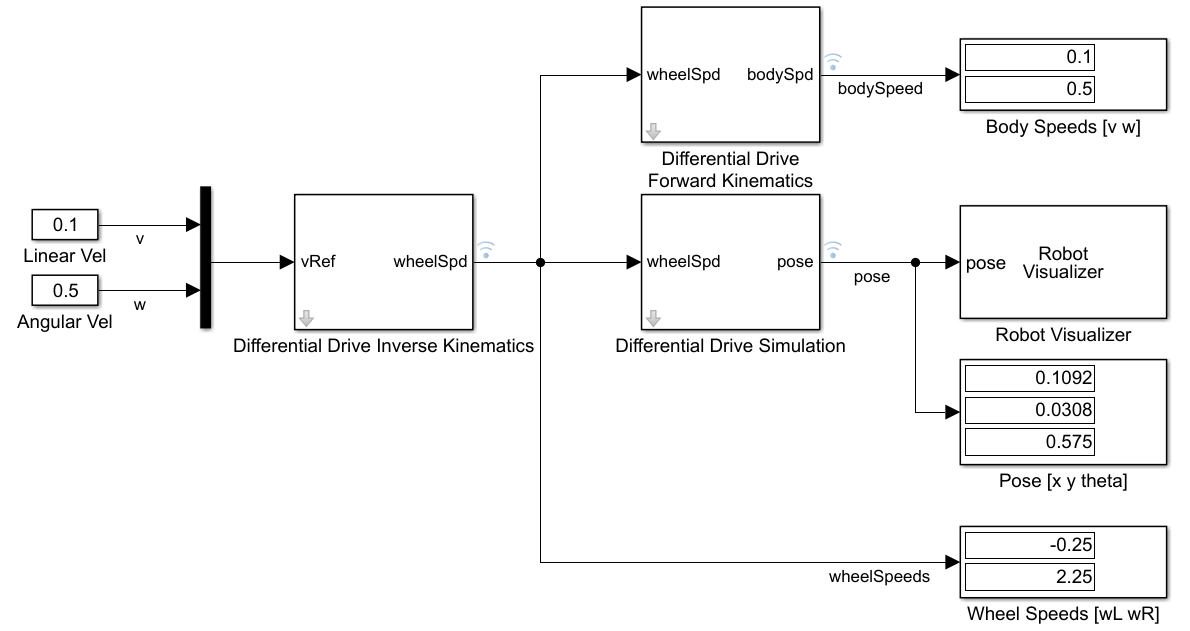

Reference examples:

- [Differential drive kinematic simulation](matlab:mrsDiffDriveModel)